--- Processing: Heel Down Side ---


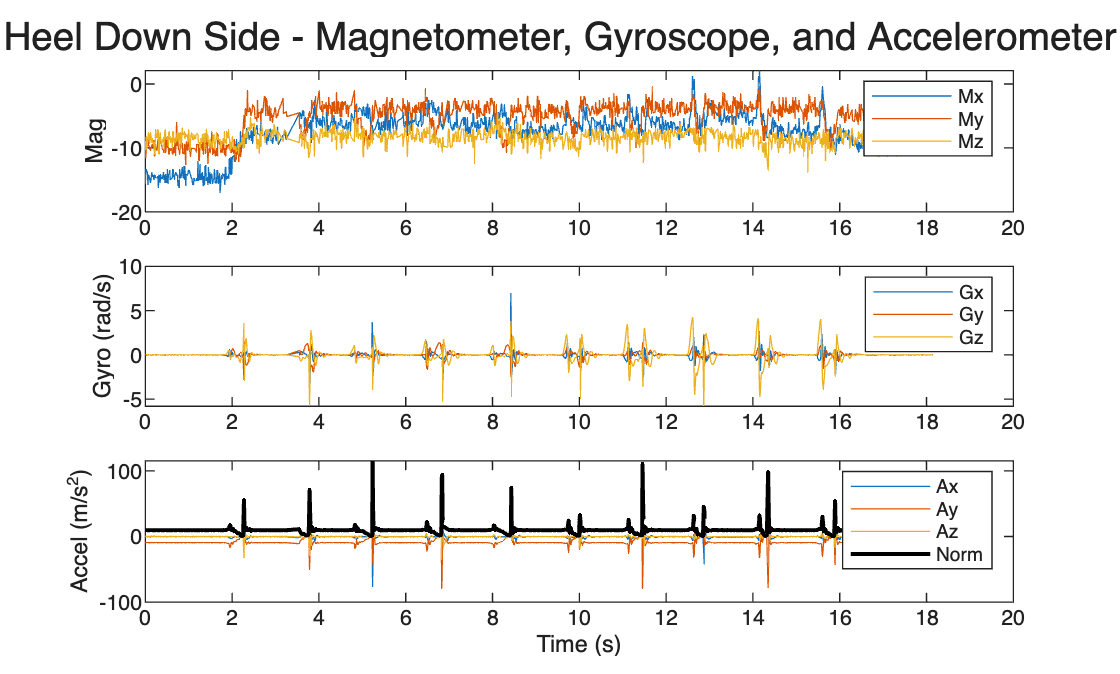

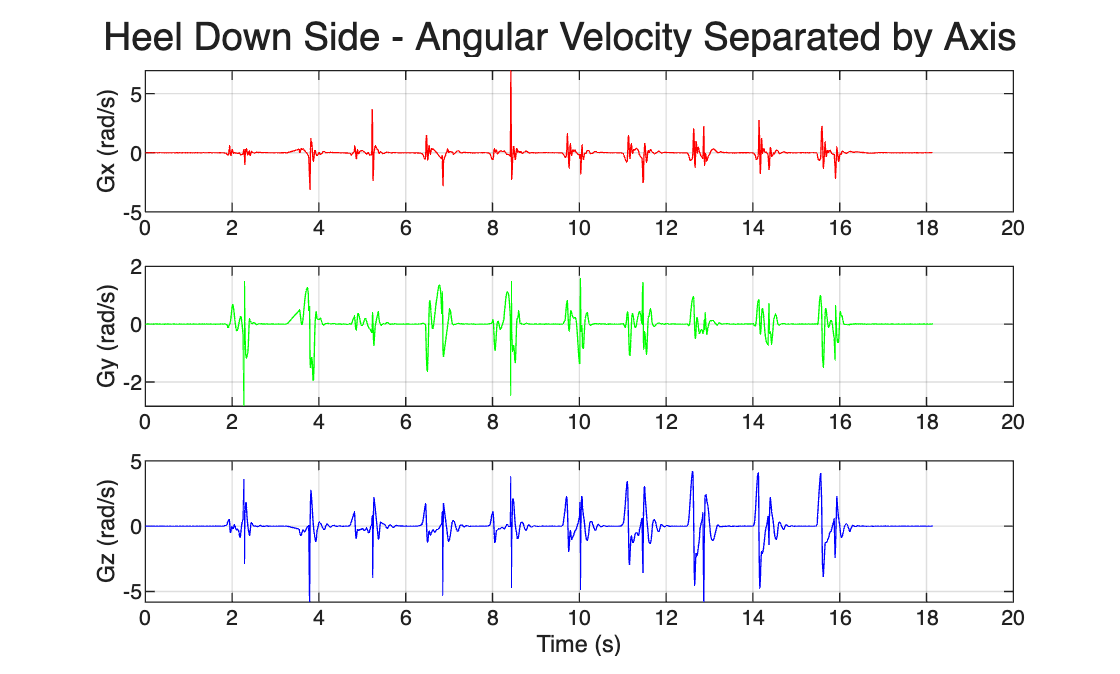

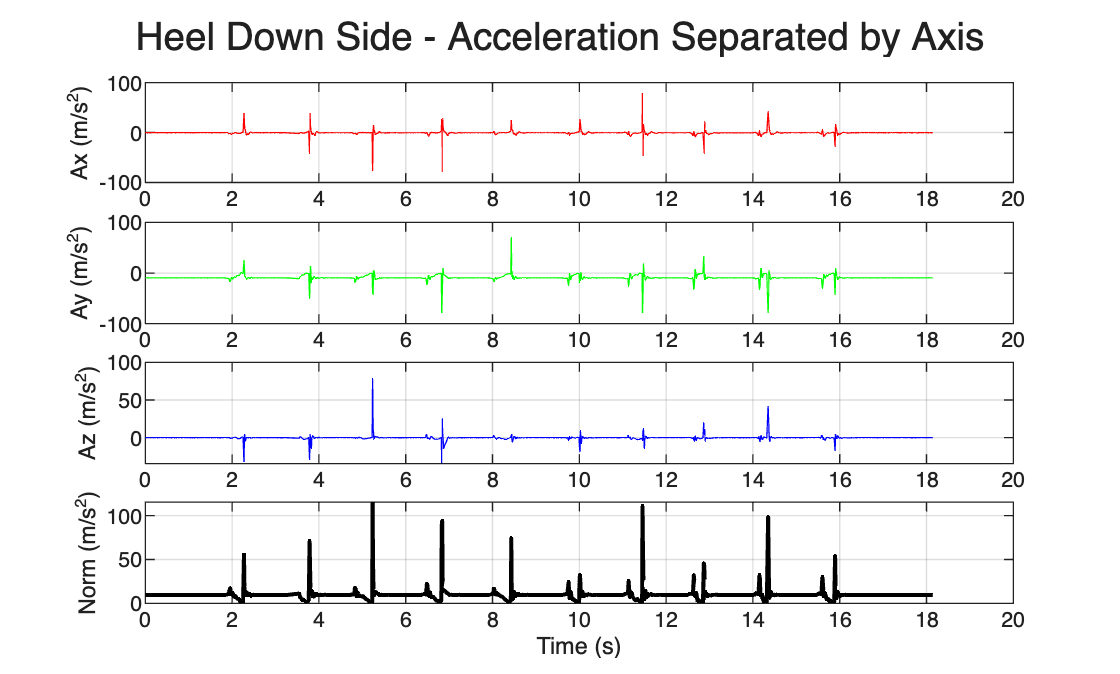

%% ROB 435 Quantifying Human Motion Through Wearable Sensors %%
%% Final Project %%
%% Authors: Lucia Lee, Nathan Kuo, Keerthi Marri, Mason Niu

clear;
close all;

% Arguments: (1) Path to CSV, (2) Name of the trial for plot titles
analyzeAndPlotIMU('initial_data/heel_down_side.csv', 'Heel Down Side');

--- Processing: Heel Up Side ---


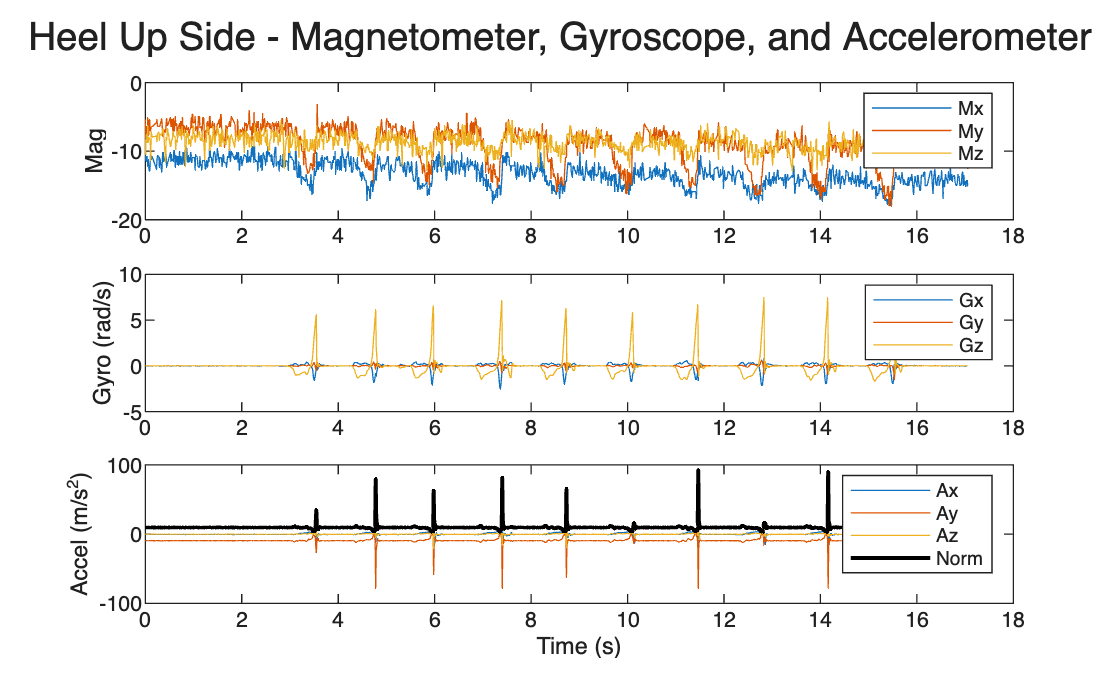

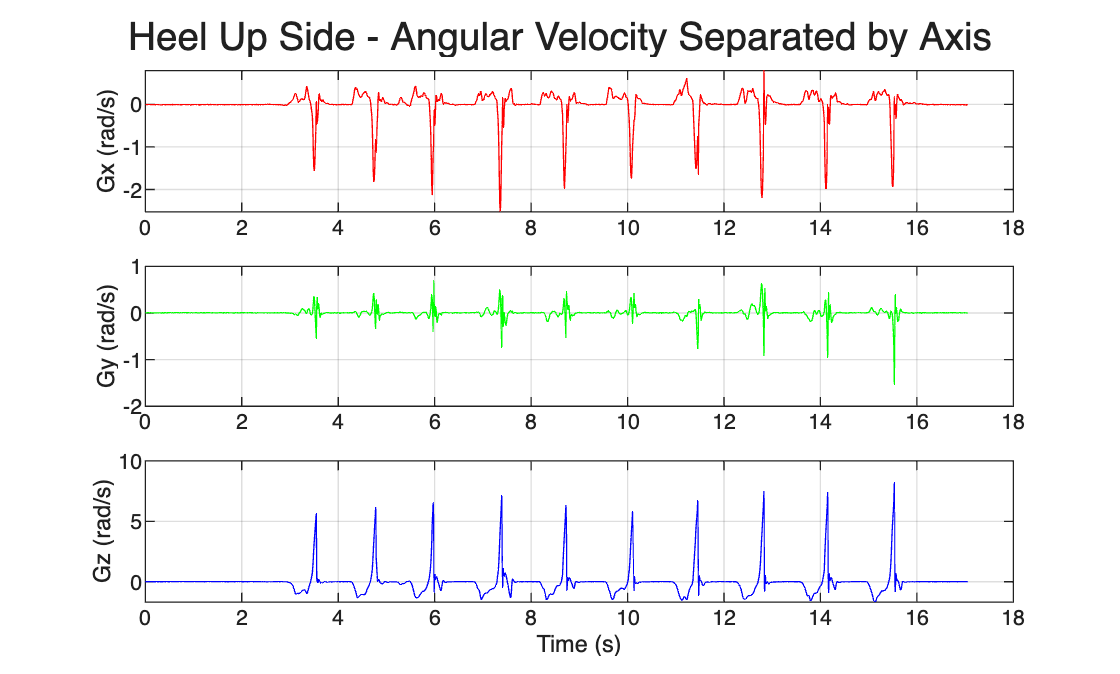

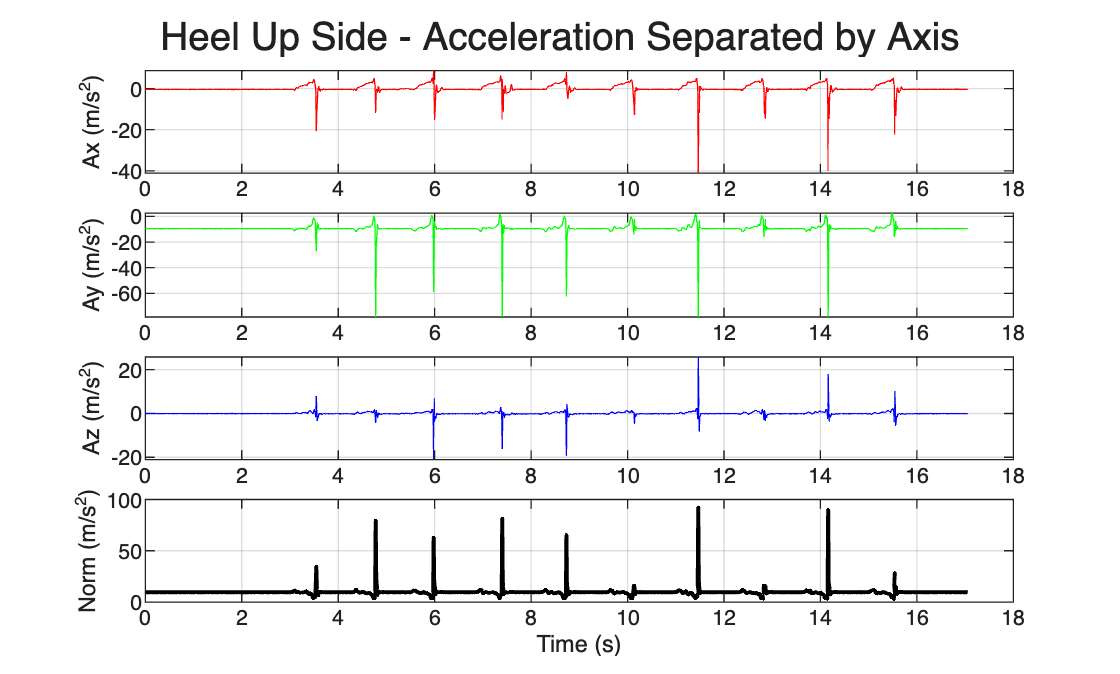

analyzeAndPlotIMU('initial_data/heel_up_side.csv', 'Heel Up Side');

--- Processing: Heel Up/Down Side ---


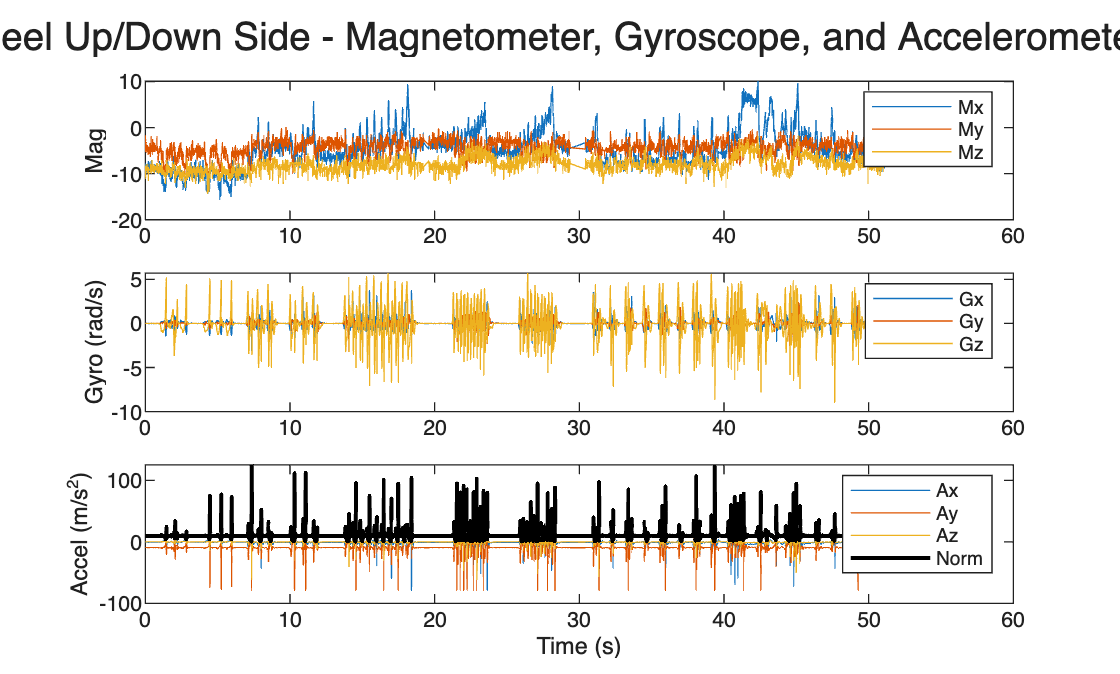

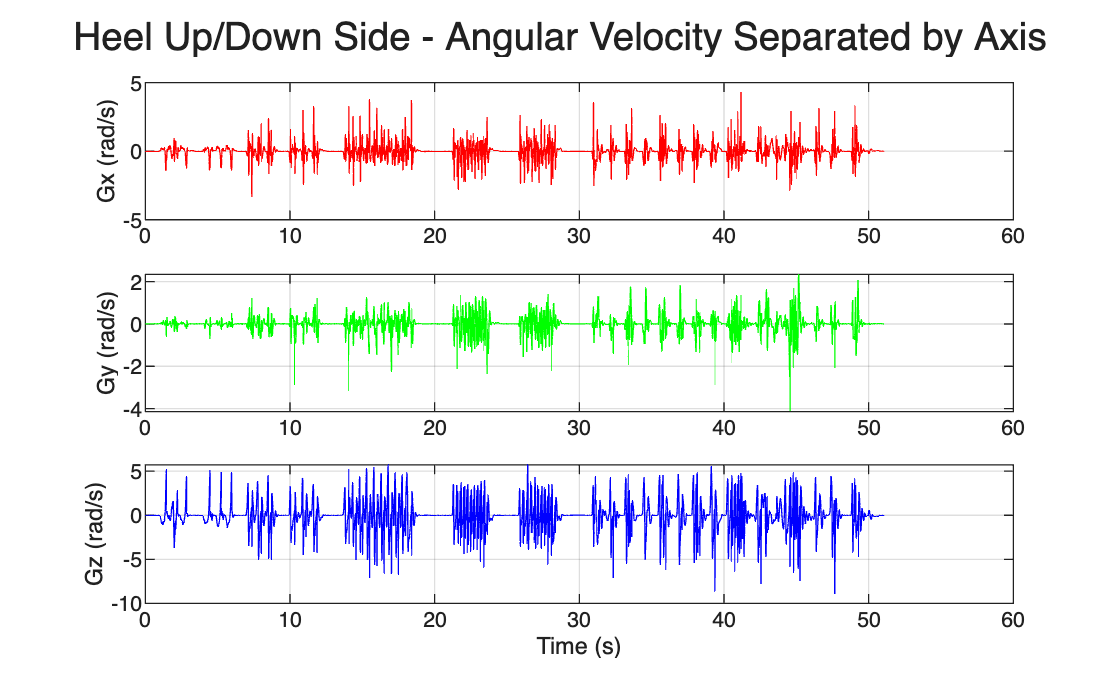

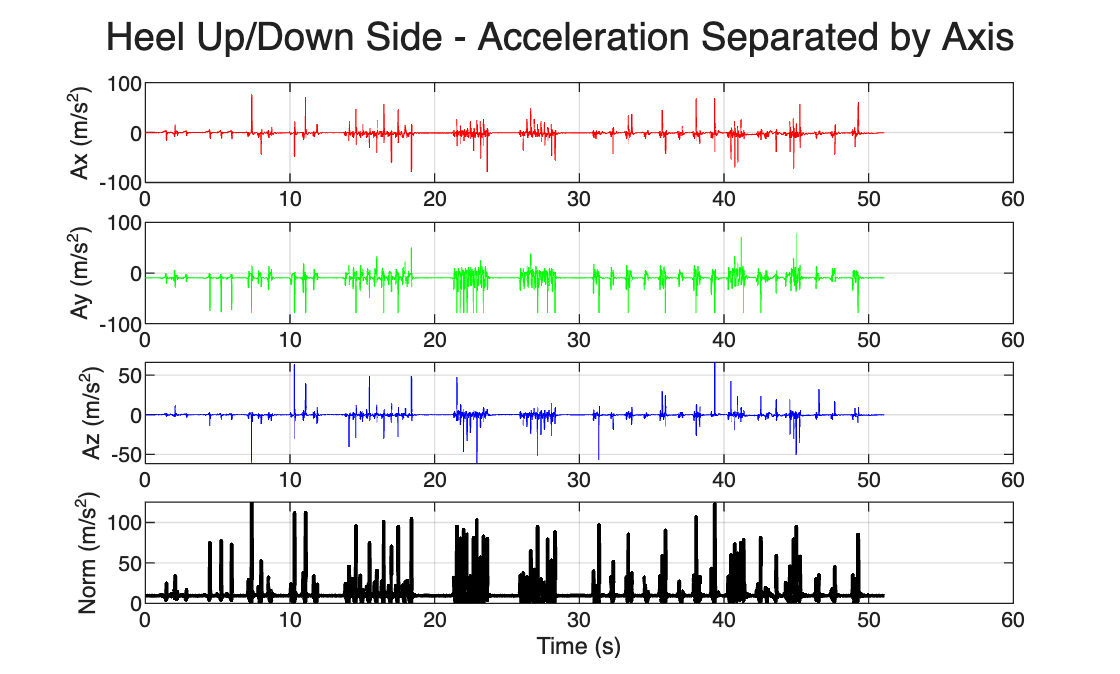

analyzeAndPlotIMU('initial_data/heel_up_down_side.csv', 'Heel Up/Down Side');



function analyzeAndPlotIMU(filename, trialName)
    fprintf('--- Processing: %s ---\n', trialName);
    
    % Load the data 
    dataTab = readtable(filename);

    % Define gravity
    g = 9.80665; %m/s^2

    % Pull out the time vector
    tvec_ms = dataTab.timestamp - dataTab.timestamp(1); % Time was recorded in ms
    tvec_s = tvec_ms / 1000; % Convert time to s

    % Pull out the angular velocity data and convert to rad/sec
    omega_x = dataTab.gyro_x * pi/180;
    omega_y = dataTab.gyro_y * pi/180;
    omega_z = dataTab.gyro_z * pi/180;

    % Pull out the accelerations, convert to units of m/s^2
    acc_x = dataTab.accl_x * g;
    acc_y = dataTab.accl_y * g;
    acc_z = dataTab.accl_z * g;

    % Pull out the magnetometer data
    mag_x = dataTab.mag_x;
    mag_y = dataTab.mag_y;
    mag_z = dataTab.mag_z;

    % Normalize the accelerometer data
    IMU_accel_norm = sqrt(acc_x.^2 + acc_y.^2 + acc_z.^2);

    % Organize the gyro, accel, and mag data
    gyros = [omega_x omega_y omega_z];
    accels = [acc_x acc_y acc_z];
    mags = [mag_x mag_y mag_z];

    % PLOT 1: All Sensors Over Time (Combined Axes)
    figure('Name', [trialName ' - All Sensor Data']);
    sgtitle([trialName ' - Magnetometer, Gyroscope, and Accelerometer']);
    
    subplot(311)
    plot(tvec_s, mags)
    legend('Mx', 'My', 'Mz')
    ylabel('Mag')

    subplot(312)
    plot(tvec_s, gyros)
    legend('Gx', 'Gy', 'Gz')
    ylabel('Gyro (rad/s)')

    subplot(313)
    plot(tvec_s, accels)
    hold on
    plot(tvec_s, IMU_accel_norm, 'k', 'LineWidth', 1.5)
    legend('Ax', 'Ay', 'Az','Norm')
    xlabel('Time (s)')
    ylabel('Accel (m/s^2)')

    % PLOT 2: Angular Velocity Separated by Axis (Spread Apart)
    figure('Name', [trialName ' - Angular Velocity Separated']);
    sgtitle([trialName ' - Angular Velocity Separated by Axis']);

    subplot(311)
    plot(tvec_s, omega_x, 'r')
    ylabel('Gx (rad/s)')
    grid on

    subplot(312)
    plot(tvec_s, omega_y, 'g')
    ylabel('Gy (rad/s)')
    grid on

    subplot(313)
    plot(tvec_s, omega_z, 'b')
    xlabel('Time (s)')
    ylabel('Gz (rad/s)')
    grid on

    % PLOT 3: Acceleration Separated by Axis (Spread Apart)
    figure('Name', [trialName ' - Acceleration Separated']);
    sgtitle([trialName ' - Acceleration Separated by Axis']);

    subplot(411)
    plot(tvec_s, acc_x, 'r')
    ylabel('Ax (m/s^2)')
    grid on

    subplot(412)
    plot(tvec_s, acc_y, 'g')
    ylabel('Ay (m/s^2)')
    grid on

    subplot(413)
    plot(tvec_s, acc_z, 'b')
    ylabel('Az (m/s^2)')
    grid on

    subplot(414)
    plot(tvec_s, IMU_accel_norm, 'k', 'LineWidth', 1.5)
    xlabel('Time (s)')
    ylabel('Norm (m/s^2)')
    grid on

end
